clearvars; close all; clc;

# Audio toolbox Simulation example

2024-04-16, JVsound, J.G. Vermond

## Introduction

Example on how to use the JVsound audio toolbox for loudspeaker and other acoustic simulations.

## Simulation

To create a simulation object, use the syntax:

% Create simulation object:
sim1        = acoustics.simulation;

A default frequency array is used. This can be overwritten by setting the property f:

sim1.f      = logspace(log10(2e1),log10(1e3),1e3);

## Speaker

A speaker, in this case a woofer, is created by:

% Create woofer object:
sp          = speaker.woofer;

We assign parameters:

sp.re       = 6;
sp.qes      = 0.38;
sp.qms      = 6.4;
sp.fs       = 32;
sp.sd       = 1680e-4;
sp.vas      = 200e-3;
sp.le       = 2.2e-3;
sp.xmax     = 15e-3;
sp.paes     = 2000;

And some additional properties:

sp.brand    = "B&C";
sp.model    = "21SW152-8";
sp.size     = 21;

## Enclosure

Creation of 2 enclosures:

- Closed box

- Bass reflex box

If a enclosure is assigned to a simulation object, it will 'inherit' the frequency vector from the simulation object.

### Closed

A closed box, with a specfic volume:

% Volume of closed box [m3]:
vol         = 200e-3;

% Create enclosure:
cb          = enclosure.closedbox(vol);

## Assign speaker and enclosure to simulation

The speaker and enclosure are added to the simulation object:

% Assign speaker to simulation object:
sim1.sp     = sp;

% Assing enclosure to simulation object:
sim1.encl   = cb;

## Sound pressure level

To calculate the sound pressure level in [dB], we need to set the generator voltage, and the distance (radius) from the speaker, $r$:

% Generator voltage [V]:
sim1.eg     = 2.83;

% Radius [m]:
sim1.r      = 1;

The sound pressure level in [dB] is now solved using the 'spl' method of the simulation class. The SPL is a function of the volume velocity radiated, which is calculated by the 'sim2port' network.

% spl method:
spl         = sim1.spl;

Results shown in the following figure:

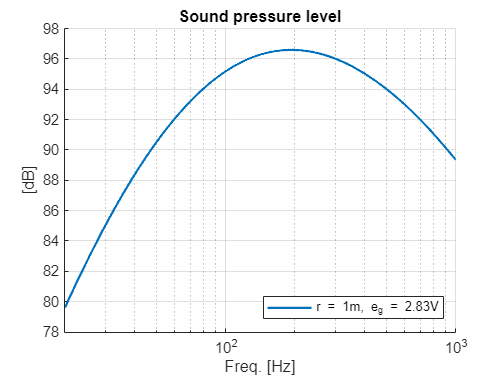

f1              = figure;
ax1             = axes(f1); hold on; grid on; 
ax1.XScale      = "log";
ax1.XLim        = [sim1.f(1) sim1.f(end)];

plot(ax1,sim1.f,spl,LineWidth=1.5);

ax1.XLabel.String   = "Freq. [Hz]";
ax1.YLabel.String   = "[dB]";
ax1.Title.String    = "Sound pressure level";

legend(ax1,"r = 1m, e_g = 2.83V",Location="southeast");